# Problem 1A

[m,n,h,t,v,IK,INa,Il,Ic,gK,gNa,I] = HH(10,0);
numI = 1;

## Action Potential

name = sprintf('SingleAP_%d.svg',numI);
figure()
plot(t,v); 
xlabel('time (ms)'); 
ylabel('voltage (mV)'); 
title('Single AP');
saveas(gcf,name)

## 1a) Evolution of m,n,h parameters

name1a = sprintf('HHparams_%d.svg',numI)
figure()
plot(t,n,t,m,t,h); 
legend('n','m','h'); 
xlabel('Time (ms)');
ylabel('Intensity');
title('HH-Parameters');
saveas(gcf,name1a)

## 1b) Relative evolution of sodium and potassium conductances

name1b = sprintf('codunctances_%d.svg',numI)
figure()
plot(t,IK,t,INa,t,Il,t,Ic);
legend('K current','Na current','Leak current','Capacitive current')
title('HH-Currents') 
xlabel('time (ms)'); 
ylabel('Current (nA)');
saveas(gcf,name1b)

## 1c) Relative evolution of capacitive, leak, sodium and potassium currents

name1c = sprintf('currents_%d.svg',numI)
figure()
plot(t,gK,t,gNa);
legend('K conductance','Na conductance');
title('HH-Conductances');
xlabel('time (ms)');
ylabel('Conductances (mS/cm^{2})');
saveas(gcf,name1c)

## 1d) Threshold and rebound spiking behavior

name1d = sprintf('thresholdNrebound_%d.svg',numI)
[m,n,h,t,v,IK,INa,Il,Ic,gK,gNa,I] = HHr(-20,0);
figure()
subplot(2,3,1)
plot(t,v)
xlabel('time (ms)'); 
ylabel('voltage (mV)');
title('Rebound Spike')
subplot(2,3,4)
plot(t,I)
xlabel('time (ms)'); 
ylabel('current (nA)');
xlabel('time (ms)'); 
ylabel('voltage (mV)');
[m,n,h,t,v,IK,INa,Il,Ic,gK,gNa,I] = HHr(0,0);
subplot(2,3,2)
plot(t,v)
xlabel('time (ms)'); 
ylabel('voltage (mV)');
title('Below Threshold')
subplot(2,3,5)
plot(t,I)
xlabel('time (ms)'); 
ylabel('current (nA)');
xlabel('time (ms)'); 
ylabel('voltage (mV)');
[m,n,h,t,v,IK,INa,Il,Ic,gK,gNa,I] = HHr(70,0);
subplot(2,3,3)
plot(t,v)
xlabel('time (ms)'); 
ylabel('voltage (mV)');
title('Above Threshold')
subplot(2,3,6)
plot(t,I)
xlabel('time (ms)'); 
ylabel('current (nA)');
xlabel('time (ms)'); 
ylabel('voltage (mV)');
saveas(gcf,name1d)

## 1e) Quadratic Fit of alpha_n

numI = 2;
name1e1 = sprintf('quadfit_%d.svg',numI)

[m,n,h,t,v,IK,INa,Il,Ic,gK,gNa,I] = HHr(10,0);
figure()
an =@(v) 0.01*(-65-v+10)./(exp((-65-v+10)/10)-1);
a = an(v)
qfit = polyfit(v,a,2);
qfity = polyval(qfit,v);
plot(v,a,'--',v,qfity)
legend('\alpha_n','Quadratic fit of \alpha_n')
xlabel('time (ms)');
ylabel('magnitude');
title('Quadratic Fit of \alpha_n of HH Model');
saveas(gcf,name1e1)

name1e2 = sprintf('quadfitCompare_%d.svg',numI)
[m,n,h,t,v,IK,INa,Il,Ic,gK,gNa,I] = HHr(10,0);
figure()
plot(t,v)
[m,n,h,t,v,IK,INa,Il,Ic,gK,gNa,I] = HHr(10,0,qfit);
hold on
plot(t,v,'--')
legend('Original','Quadratic')
xlabel('time (ms)');
ylabel('voltage (mV)');
title('Comparison of Original and Quadratic \alpha_n')
saveas(gcf,name1e2)

# Problem 2

## 2a) Simple Integrate & Fire Neuron (IAF)

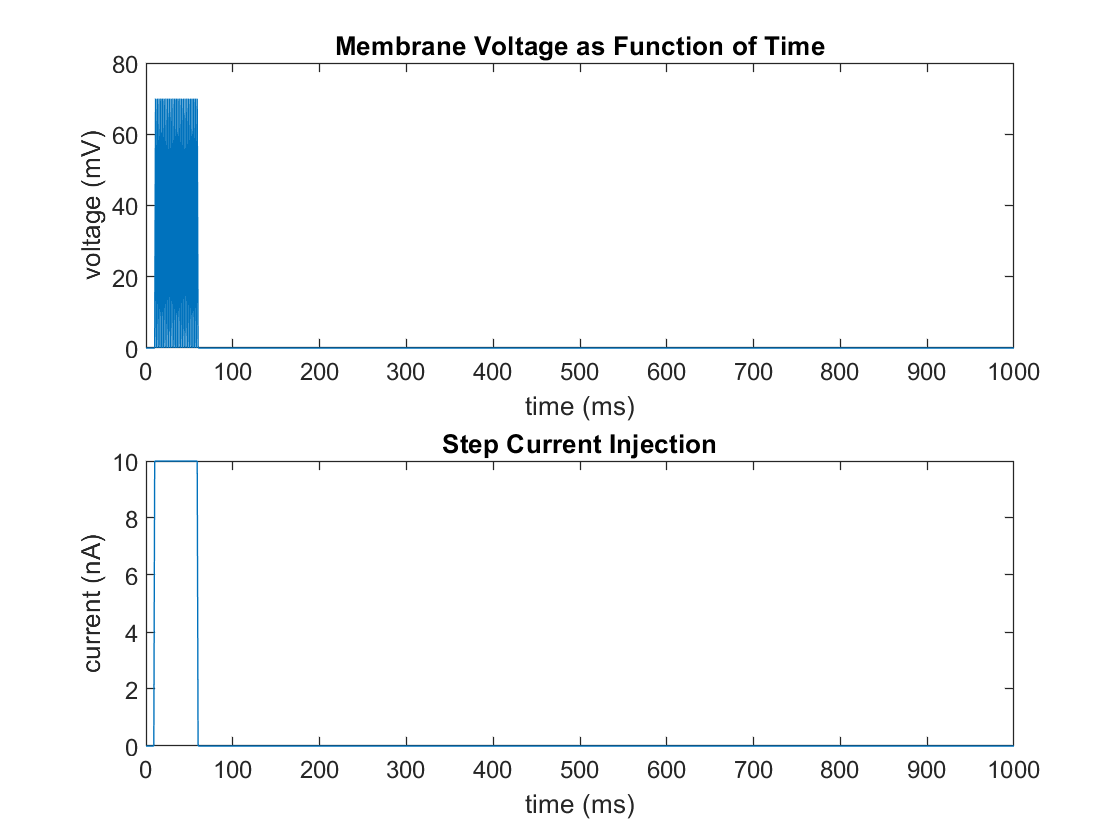

C=1; % Membrane Capcitance nF
dt = 1; % ms
t=0:dt:1000; % Time Array ms
R = 1; % MOhms
I = zeros(1,length(t)); % current (nA)
v = zeros(1,length(t)); % voltage (ms)

for i=1:length(t)-1
    if (t(i) >= 10 && t(i) < 60) 
        I(i) = 10; % current (nA)
    else 
        I(i) = 0; % current (nA)
    end
    
    dvdt(i)= (dt/C)*(I(i)-v(i)/R) + v(i); % voltage (mV)
    
    if v(i) >= 5 % voltage (mV)
        v(i) = 70; % voltage (mV)
        v(i+1) = 0; % voltage (mV)
    elseif v(i) < 5 % voltage (mV)
        v(i+1) = dvdt(i) +v(i); % voltage (mV)
    end
end

figure()
subplot(2,1,1)
plot(t,v);
title('Membrane Voltage as Function of Time')
xlabel('time (ms)');
ylabel('voltage (mV)');
subplot(2,1,2)
plot(t,I);
title('Step Current Injection')
xlabel('time (ms)');
ylabel('current (nA)');

f=[1,2,5,10,20,50,100]*1e-3;
for i = 1:length(f)
   sf(i) = plotFreq(f(i))
end

% Spike Count
figure()
spk=[1, 2,5,10, 20, 50, 100];
plot(spk,sf);
title('Spike Count vs. Stimulus Frequency');
xlabel('Frequency (Hz)');
ylabel('Spike Count');

## Part B

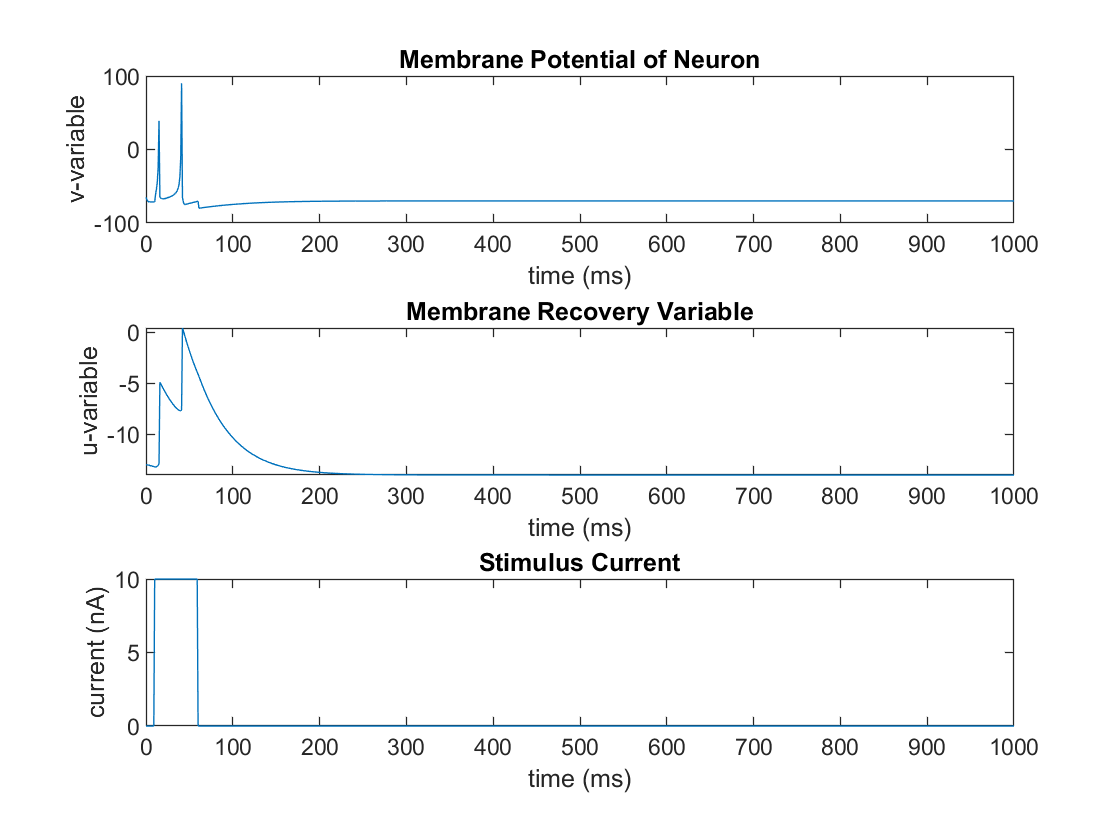


C=1; % Membrane Capcitance uF/cm^2
dt = 1; % ms
t=0:dt:1000; % Time Array ms
R = 10e6; % MOhms
a = 0.02;b=0.2;c=-65;d=8;
I = zeros(1,length(t)); % current (nA)
u = zeros(1,length(t)); % current (nA)
v = zeros(1,length(t)); % current (nA)

for i=1:length(t)-1
    I(1) = 0; % current (nA)
    v(1) = -65; % voltage (ms)
    u(1) = b*v(1);
    if (t(i) >= 10 && t(i) < 60)
        I(i) = 10; % current (nA)
    else
        I(i) = 0; % current (nA)
    end
  
    dvdt(i)= 0.04*v(i).^2 + 5*v(i) +140 - u(i) + I(i); % voltage (mV)
    dudt(i) = a*(b*v(i)-u(i));
    if v(i) >= 30e-3 % voltage (mV)
        v(i+1) = c; % voltage (mV)
        u(i+1) = u(i)+d;
    else % voltage (mV)
         v(i+1) = v(i) + dvdt(i); % voltage (mV)
         u(i+1) = u(i) + dudt(i);
    end
end
figure()
subplot(3,1,1)
plot(t,v);
title('Membrane Potential of Neuron')
xlabel('time (ms)');
ylabel('v-variable');
% xlim([0 30])
subplot(3,1,2)
plot(t,u);
title('Membrane Recovery Variable')
xlabel('time (ms)');
ylabel('u-variable');
subplot(3,1,3)
plot(t,I)
%xlim([0 30])
title('Stimulus Current')
xlabel('time (ms)');
ylabel('current (nA)');

name = 'freqPlotB_1Hz.jpg'

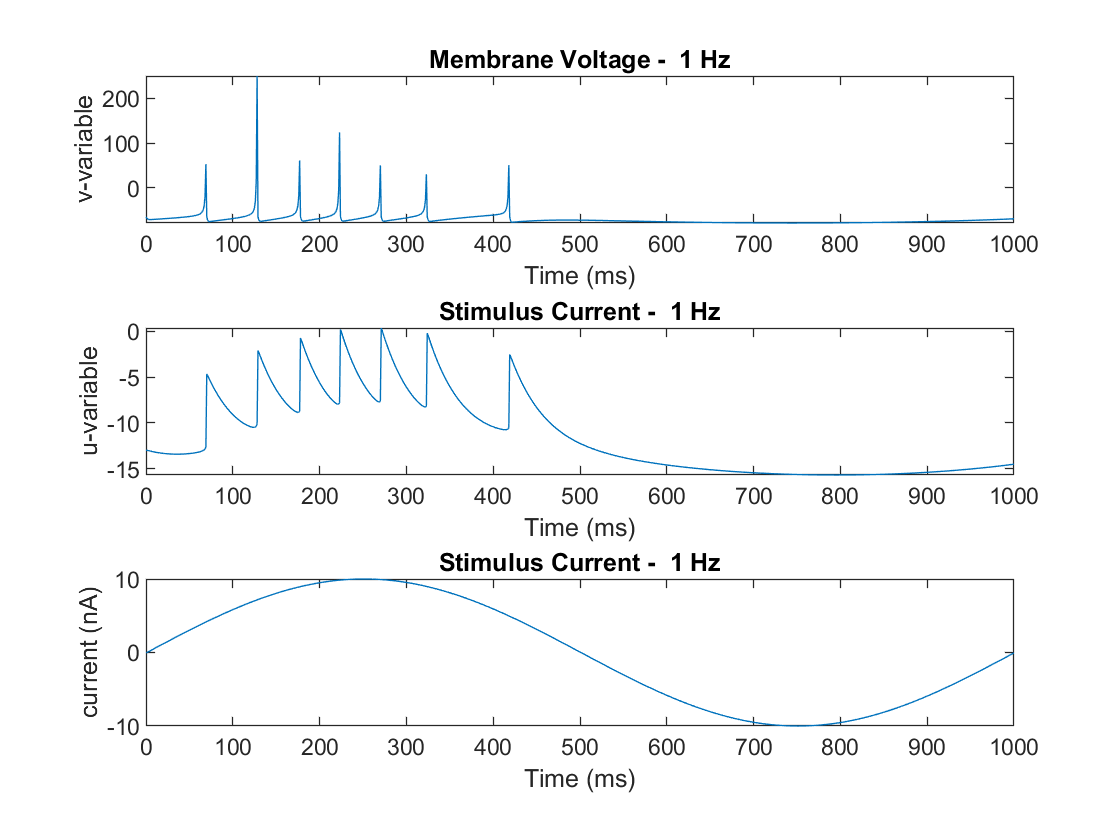

sf =      7     0     0     0     0     0     0


name = 'freqPlotB_2Hz.jpg'

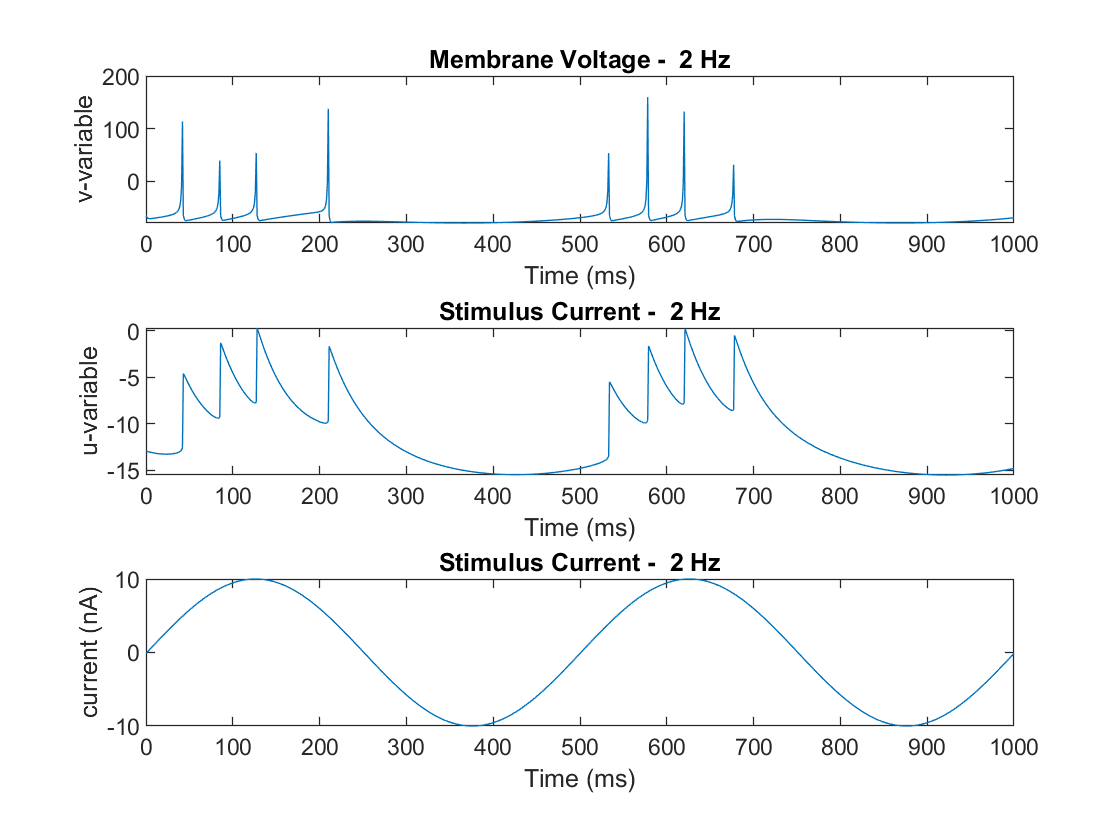

sf =      7     8     0     0     0     0     0


name = 'freqPlotB_5Hz.jpg'

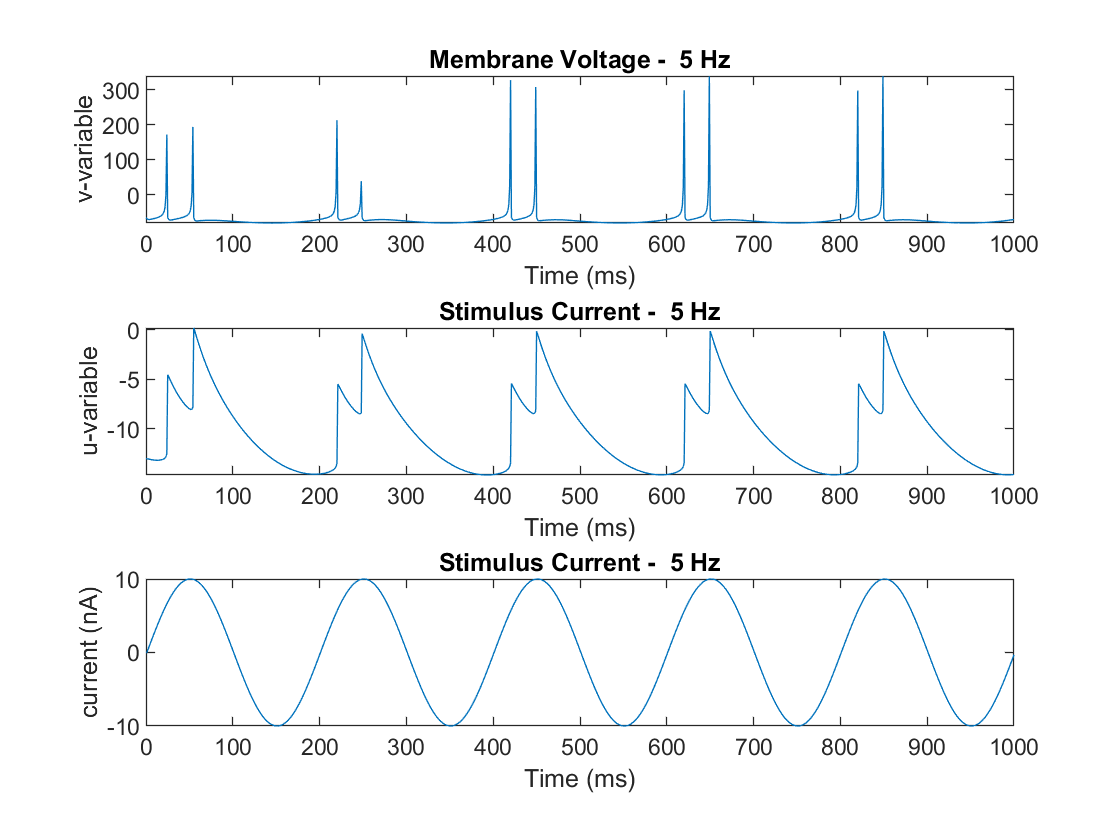

sf =      7     8    10     0     0     0     0


name = 'freqPlotB_10Hz.jpg'

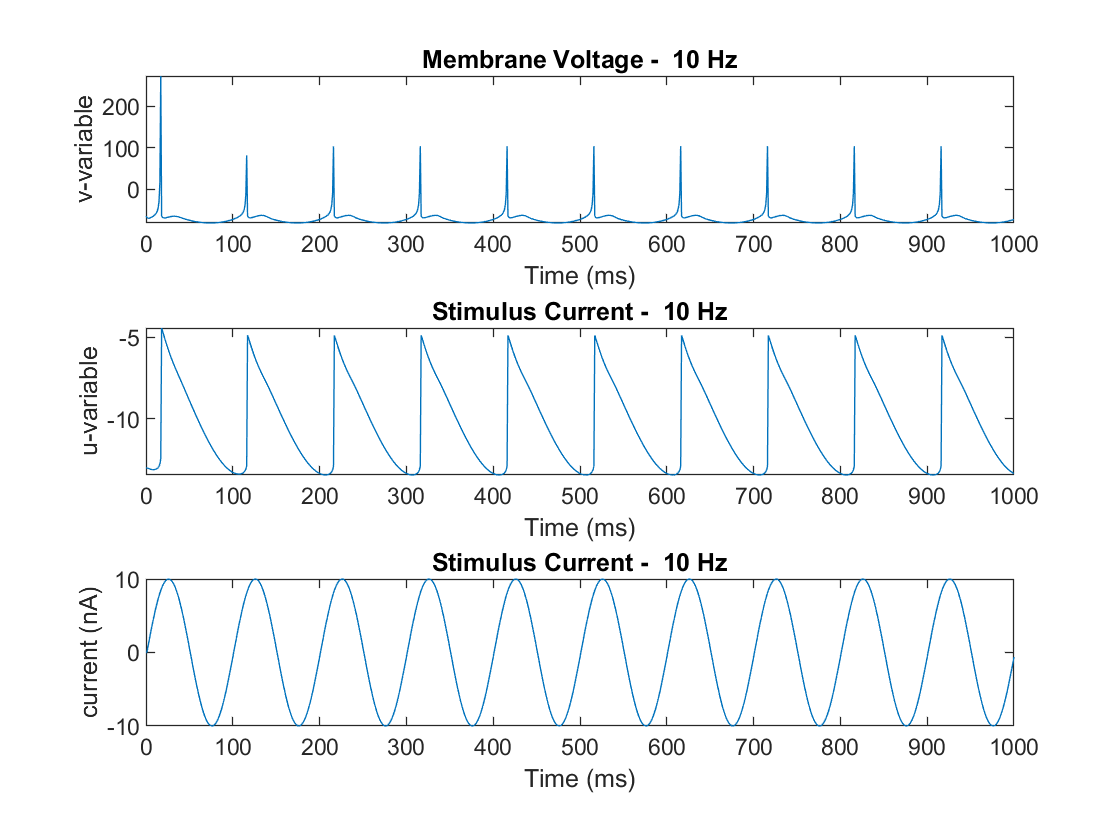

sf =      7     8    10    10     0     0     0


name = 'freqPlotB_20Hz.jpg'

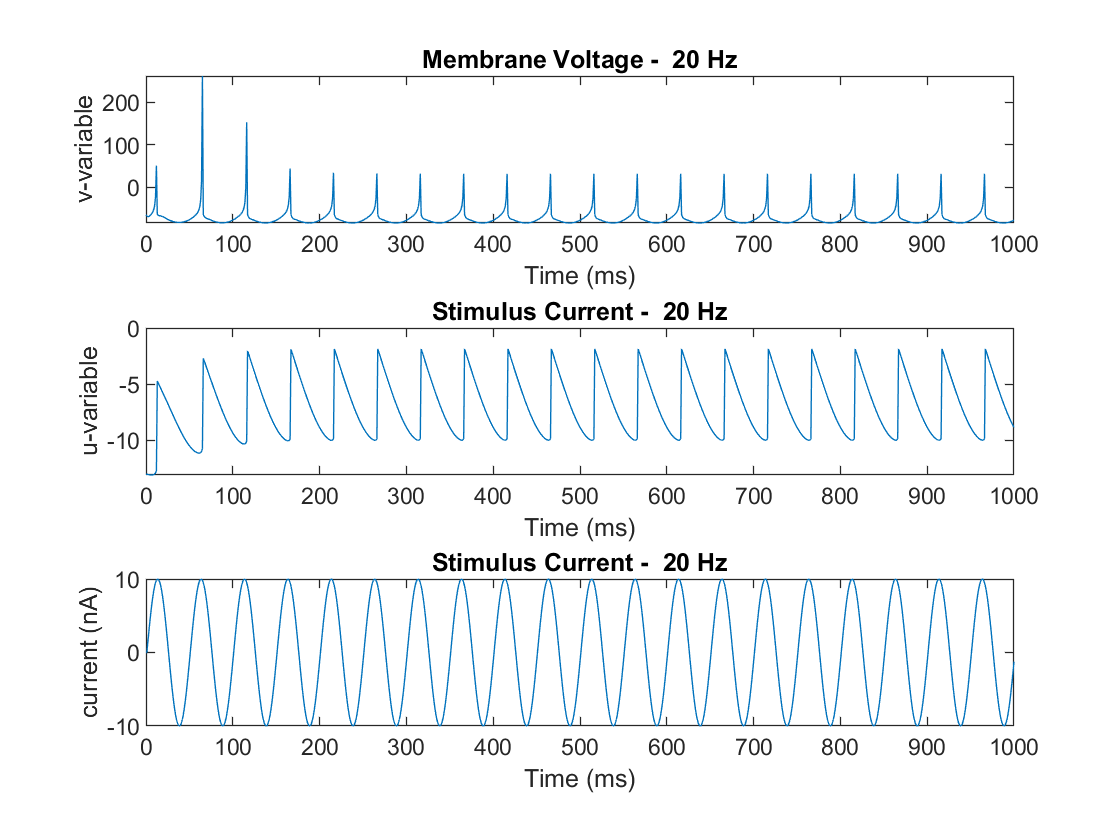

sf =      7     8    10    10    20     0     0


name = 'freqPlotB_50Hz.jpg'

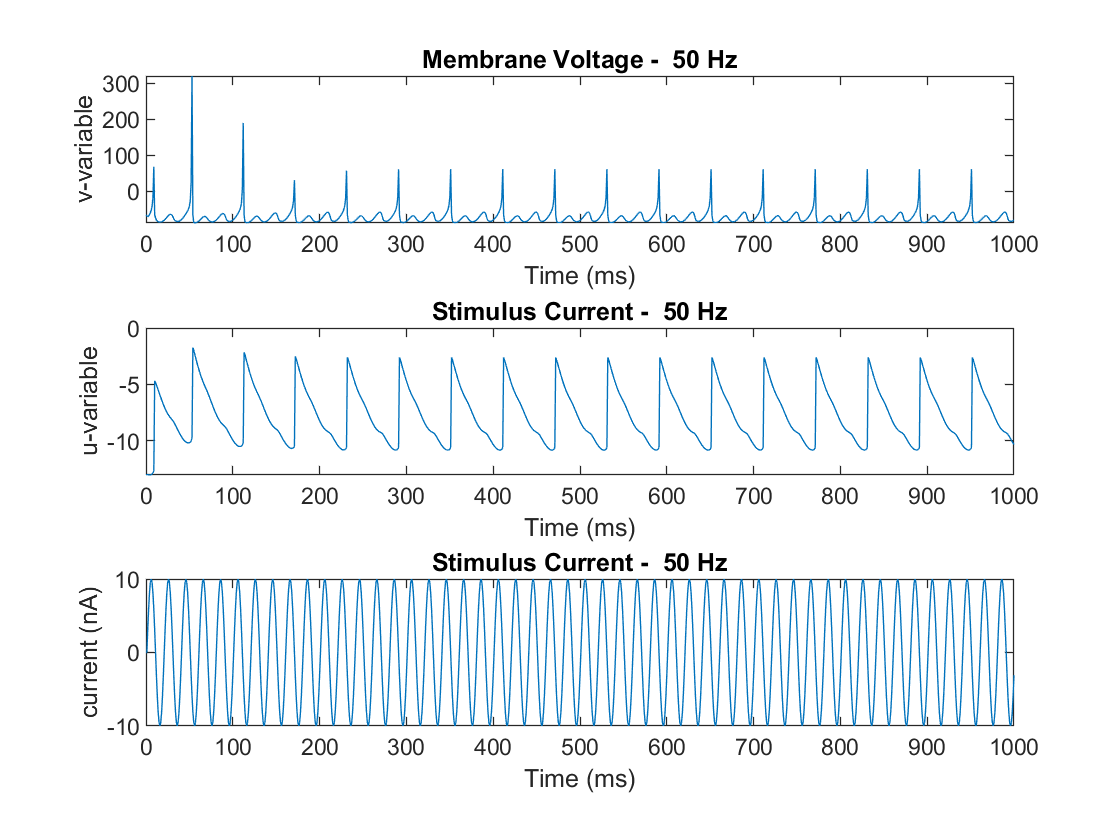

sf =      7     8    10    10    20    17     0


name = 'freqPlotB_100Hz.jpg'

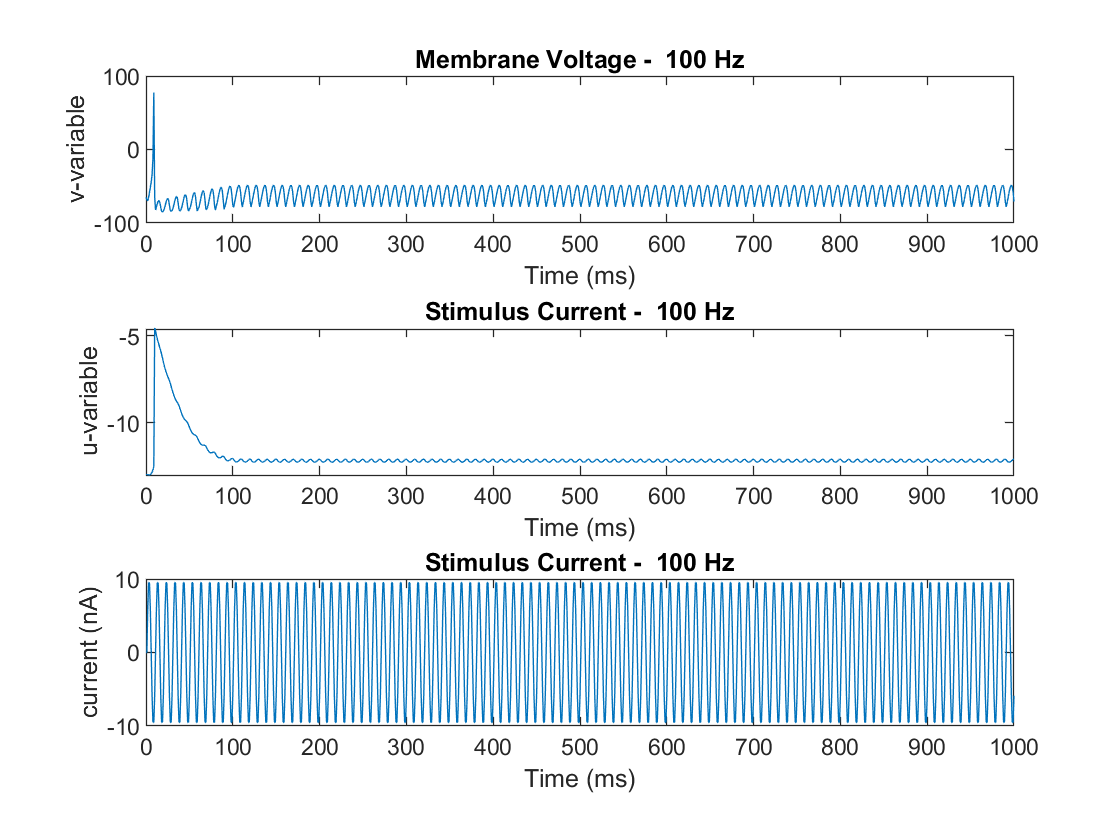

sf =      7     8    10    10    20    17     1


f=[1,2,5,10,20,50,100]*1e-3;
for i = 1:length(f)
   sf(i) = plotFreqB(f(i))
end

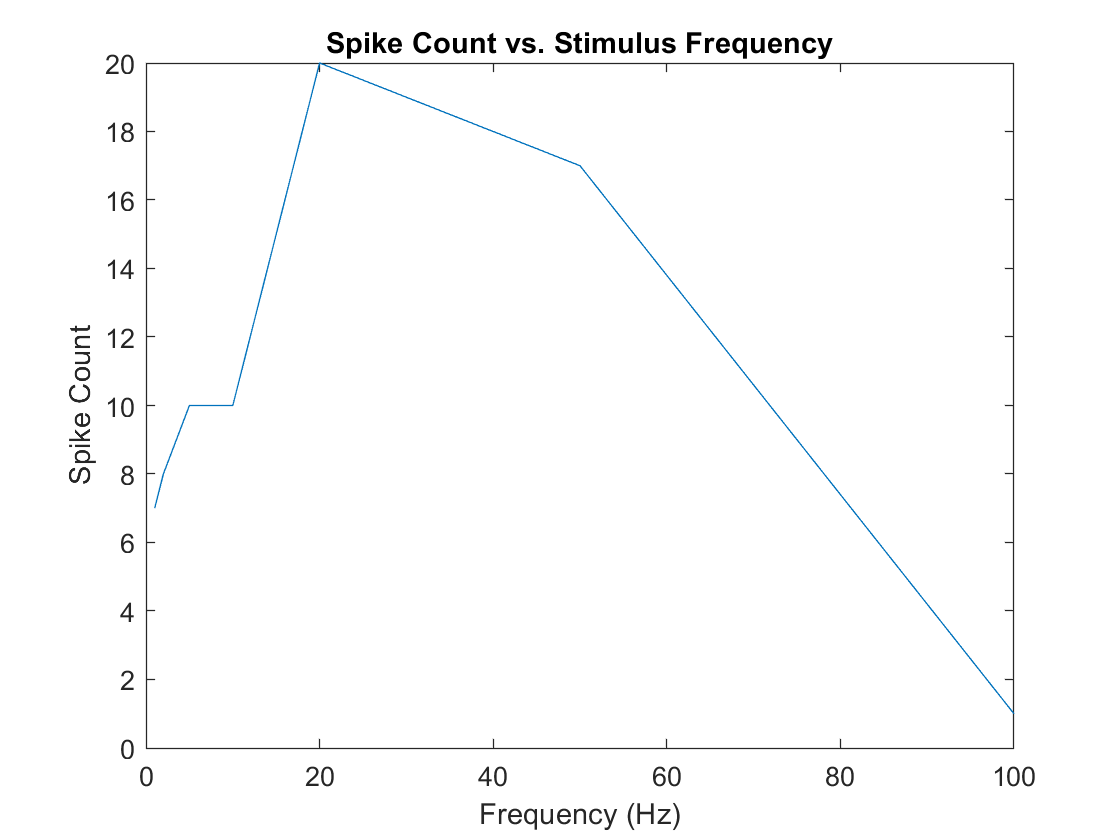

% Spike Count
figure()
spk=[1, 2,5,10, 20, 50, 100];
plot(spk,sf);
title('Spike Count vs. Stimulus Frequency');
xlabel('Frequency (Hz)');
ylabel('Spike Count');

## Problem 2c


C = 1;
R = 10;
E = -15;

tau_s = 15;
tau_t = 50;
gpeak = 0.1;
g = gpeak ./(tau_s/2.7183);               
t= 0:1:1500;                
I1 = 1.1;
I2 = 0.9;

v1 = zeros(1,1501);
v2 = zeros(1,1501);
theta1 = zeros(1,1501);
theta2 = zeros(1,1501);
g1 = zeros(1,1501);
g2 = zeros(1,1501);
z1 = zeros(1,1501);
z2 = zeros(1,1501);
u1 = zeros(1,1501);
u2 = zeros(1,1501);

for i=1:length(t)-1
    
    if v1(i) >= 70
        u1(i) = 1;
    else
        u1(i) = 0;
    end
    
    if v2(i) >= 70
        u2(i) = 1;
    else
        u2(i) = 0;
    end
        
        z1(i+1) = z1(i) + (-z1(i)/tau_s + g*u2(i));
        z2(i+1) = z2(i) + (-z2(i)/tau_s + g*u1(i));
        g1(i+1) = g1(i) +(-g1(i)/tau_s + z1(i));
        g2(i+1) = g2(i) +(-g2(i)/tau_s + z2(i));
        
        % update threshold
        dtheta1 = (-theta1(i) + v1(i))/tau_t;
        dtheta2 = (-theta2(i) + v2(i))/tau_t;
        theta1(i+1) = theta1(i) + dtheta1;
        theta2(i+1) = theta2(i) + dtheta2;

        % update membrane voltage
        if(v1(i) >= 70)                  
            v1(i+1) = E; 
        else                           
            dvdt1 = (-v1(i)/R + I1 - (g1(i).*(v1(i) - E)))/C; 
            v1(i+1) = v1(i) + dvdt1; 
        end
       
        
        if(v2(i) >= 70)                  
            v2(i+1) = E; 
        else                           
            dvdt2 = (-v2(i)/R + I2 - (g2(i).*(v2(i) - E)))/C; 
            v2(i+1) = v2(i) + dvdt2; 
        end
        
        if(v1(i+1) >= theta1(i))             
            v1(i+1) = 70; 
        elseif(v2(i+1) >= theta2(i))             
            v2(i+1) = 70; 
        end
          
end   

subplot(2,1,1)
plot(t,v1,t,theta1);
title('Two-Neuron Oscillator: Reciprocal Inhibition');
xlabel('time (msec)');
ylabel('voltage (mV)');
legend('Neuron 1','Theta 1');
subplot(2,1,2)
plot(t,v2,t,theta2);
xlabel('time (msec)');
ylabel('voltage (mV)');
legend('Neuron 2', 'Theta 2');


# Problem 3


trialtime = 0:1e-3:20;
fire = zeros(length(trialtime),1);
start2 = round((start * 1e-3),3);
stop2  = round((stop * 1e-3),3);
for n = 1:23  
    parfor i = 1:length(trialtime)
        if trialtime(i) >= start2(n) && trialtime(i) <= stop2(n)
            fire(i) = 1;
        elseif trialtime(i) > stop(n)
            fire(i) = 0;
        end
    end
end
%% Plot Stimulus Plot
figure()
plot(trialtime,fire);
ax = gca;
ax.YAxis.TickValues = [0 1];
title ('Stimulus');
xlabel('Time (s)');
ylabel('Binary Firing');

%%
totaltime = 0:1e-3:100;
R = zeros(length(totaltime),1);
spikes = round(spikes,3);
tot = round(totaltime,3);
%%
for j = 1:length(spikes)
    parfor k = 1:length(tot)
            if spikes(j) == tot(k)
                R(k) = 1;
            end
    end
end
figure()
plot(tot,R);
ax2 = gca;
ax2.YAxis.TickValues = [0 1];
title ('Trials');
xlabel('Time (s)');
ylabel('Binary Firing');
%% Separating into 5 trials
% Response from Trial 1 (0-20s)
R1 = R(1:20e3+1);
% Response from Trial 2 (20-40s)
R2 = R(20e3+2:40e3+1);
R2(end+1) = 0;
% Response from Trial 3 (40-60s)
R3 = R(40e3+2:60e3+1);
R3(end+1) = 0;
% Response from Trial 4 (60-80s)
R4 = R(60e3+2:80e3+1);
R4(end+1) = 0;
% Response from Trial 5 (80-100s)
R5 = R(80e3+2:100e3+1);
R5(end+1) = 0;

%% Plotting Trials
figure()
subplot(5,1,1)
plot(trialtime,R1);
ax3 = gca;
ax3.YAxis.TickValues = [0 1];
title ('Trial 1');
xlabel('Time (s)');
ylabel('Binary Firing');

subplot(5,1,2)
plot(trialtime,R2);
ax3 = gca;
ax3.YAxis.TickValues = [0 1];
title ('Trial 2');
xlabel('Time (s)');
ylabel('Binary Firing');

subplot(5,1,3)
plot(trialtime,R3);
ax3 = gca;
ax3.YAxis.TickValues = [0 1];
title ('Trial 3');
xlabel('Time (s)');
ylabel('Binary Firing');

subplot(5,1,4)
plot(trialtime,R4);
ax3 = gca;
ax3.YAxis.TickValues = [0 1];
title ('Trial 4');
xlabel('Time (s)');
ylabel('Binary Firing');

subplot(5,1,5)
plot(trialtime,R5);
ax3 = gca;
ax3.YAxis.TickValues = [0 1];
title ('Trial 5');
xlabel('Time (s)');
ylabel('Binary Firing');
stim = zeros(length(trialtime),1);
for n = 1:23
    stim(trialtime >= start2(n) & trialtime <= stop2(n)) = 1;
end

w1 = 1:0.1e3:18e3+1;
w2 = 2e3+1:0.1e3:20e3+1;

S = zeros(length(w1),length(w1(1):0.1e3:w2(1)));
for i = 1:length(w1)
    ind1 = w1(i);
    ind2 = w2(i);
    S(i,:) = stim(ind1:0.1e3:ind2)';
end
Sall = vertcat(S,S,S,S,S);

fire = vertcat(R1',R2',R3',R4',R5');
w1 = 1:0.1e3:18e3+1;
w2 = 2e3+1:0.1e3:20e3+1;
for k = 1:5
        for i = 1:length(w1)
            ind1 = w1(i);
            ind2 = w2(i);
            Resp(k,i) = sum(fire(k,ind1:ind2))/20;
        end
end

Rall = [Resp(1,:),Resp(2,:),Resp(3,:),Resp(4,:),Resp(5,:)]';

% Responses 1-4
Rr14 = Rall(1:724);
% Response 5
Rr5 = Rall(725:end);

subplot(2,1,1)
plot(Rr14);
xlabel('Time (ms)');
ylabel('Response Rate [# of spikes per 100 ms]');
title('Average Response Rate from 4 Trials');
subplot(2,1,2)
plot(Rr5);
xlabel('Time (ms)');
ylabel('Response Rate [# of spikes per 100 ms]');
title('Response Rate from Trial 5');

Ss14 = Sall(1:724,:);
Ss5 = Sall(725:end,:);
% Calculating the linear filter from the first 4 trials
Sinv = pinv(Ss14);
W = Sinv*Rr14;
Sinv5 = pinv(Ss5);
W5 = Sinv5*Rr5;
figure()
plot(W);
hold on
plot(W5);
title('Comparisons of Linear Filters: Averaged and Trial 5');
ylabel('Weighting of Stimulus');
xlabel('Lag Time (ms)');
legend('Averaged','Trial 5');

%% Test
R5test = Ss5*W;
Rr5test = Ss5*W5;
figure()
plot(R5test);
hold on
plot(Rr5test);
plot(Rr5);
title('Comparison of Predicted and Actual Responses');
xlabel('Time (ms)');
ylabel('Response Rate [# of spikes per 100 ms]');
legend('Predicted Response w/ Avg. Filter','Predicted Response w/ Direct Filter','Actual Response');
hold off


# Problem 4

spk = Sall*W;
spktime = 0:length(spk)-1;
max_spk = max(spk);
u = rand(size(spktime));
train = [];
for m = 1:length(spk)
    if u(m) <=  (spk(m)/max_spk)
        train(m) = 1;
    else
        train(m) = 0;
    end
end
figure()
plot(spktime,train);
xlabel('time (ms)');
ylabel('Amplitude')
title('Spike Train')
isi = diff(find(train>0));
mean_isi = mean(isi,2);
std_isi = std(isi);
var_isi = var(isi);
fannofactor = var_isi/mean_isi
coeff_var = std_isi/mean_isi

bin = 0.001;
x = 0:bin:50;
hist(isi, x);
title('ISI Distribution');
ylabel('# of Spikes');
xlabel('ISI (ms)');
%xlim([0 100]);


function [m,n,h,t,v,IK,INa,Il,Ic,gK,gNa,I] = HH(I1,I2,qfit)

    if nargin == 3
        an = @(v) polyval(qfit,v);
    else
        an =@(v) 0.01*(-65-v+10)/(exp((-65-v+10)/10)-1);
    end
    C= 1; % Membrane Capcitance uF/cm^2 
    dt = 0.01; 
    t=0:dt:100; %Time Array ms
    I = zeros(1,length(t)); % current (nA)
    v = zeros(1,length(t)); % voltage (ms)
    VNa=55; % mv Na reversal potential 
    VK=-77; % mv K reversal potential 
    Vl=-61; % mv Leakage reversal potential
     
    g_Na=120; % mS/cm^2 Na conductance 
    g_K=36; % mS/cm^2 K conductance 
    g_l=0.3; % mS/cm^2 Leakage conductance
     
    v(1)=-65; 
    
     
     
    am = @(v) 0.1*(-65-v+25)/(exp((-65-v+25)/10)-1); 
    ah = @(v) 0.07*exp((-65-(v))/20);
    bn = @(v) 0.125 * exp((-65-v)/80); 
    bm = @(v) 4 * exp((-65-v)/18);
    bh = @(v) 1/(exp((30-65-v)/10) + 1);
    
    m(1)= am(v(1))/(am(v(1))+bm(v(1))); 
    n(1)= an(v(1))/(an(v(1))+bn(v(1))); 
    h(1)= ah(v(1))/(ah(v(1))+bh(v(1))); 
    
    for i=1:length(t)-1
        if (t(i) >= 5 && t(i) < 15)
            I(i) = I1; % current (nA)
        elseif t(i)>15 
            I(i) = I2; % current (nA)
        end
        %Euler method to find the next m/n/h value 
        m(i+1)=m(i)+dt*((am(v(i))*(1-m(i)))-(bm(v(i))*m(i))); 
        n(i+1)=n(i)+dt*((an(v(i))*(1-n(i)))-(bn(v(i))*n(i))); 
        h(i+1)=h(i)+dt*((ah(v(i))*(1-h(i)))-(bh(v(i))*h(i))); 
        gNa(i+1)=g_Na*m(i)^3*h(i); 
        gK(i+1)=g_K*n(i)^4; 
        gl =g_l;
        
         INa(i+1)=gNa(i)*(v(i)-VNa); 
         IK(i+1)=gK(i)*(v(i)-VK); 
         Il(i+1)=gl*(v(i)-Vl); 
         Ic(i+1) = -INa(i)-IK(i)-Il(i);
     
         %Euler method to find the next voltage value 
         v(i+1)= v(i)+(dt)*((1/C)*(I(i)-(INa(i)+IK(i)+Il(i))));
    end   
    
end

function [m,n,h,t,v,IK,INa,Il,Ic,gK,gNa,I] = HHr(I1,I2,qfit)

    if nargin == 3
        an = @(v) polyval(qfit,v);
    else
        an =@(v) 0.01*(-65-v+10)/(exp((-65-v+10)/10)-1);
    end
    C= 1; % Membrane Capcitance uF/cm^2 
    dt = 0.001; 
    t=0:dt:100; %Time Array ms
    I = zeros(1,length(t)); % current (nA)
    v = zeros(1,length(t)); % voltage (ms)
    VNa=55; % mv Na reversal potential 
    VK=-77; % mv K reversal potential 
    Vl=-61; % mv Leakage reversal potential
     
    g_Na=120; % mS/cm^2 Na conductance 
    g_K=36; % mS/cm^2 K conductance 
    g_l=0.3; % mS/cm^2 Leakage conductance
     
    v(1)=-65; 
    
     
     
    am = @(v) 0.1*(-65-v+25)/(exp((-65-v+25)/10)-1); 
    ah = @(v) 0.07*exp((-65-(v))/20);
    bn = @(v) 0.125 * exp((-65-v)/80); 
    bm = @(v) 4 * exp((-65-v)/18);
    bh = @(v) 1/(exp((30-65-v)/10) + 1);
    
    m(1)= am(v(1))/(am(v(1))+bm(v(1))); 
    n(1)= an(v(1))/(an(v(1))+bn(v(1))); 
    h(1)= ah(v(1))/(ah(v(1))+bh(v(1))); 
    
    for i=1:length(t)-1
        if (t(i) >= 5 && t(i) < 15)
            I(i) = I1; % current (nA)
        elseif t(i)>15 
            I(i) = I2; % current (nA)
        end
        %Euler method to find the next m/n/h value 
        m(i+1)= am(v(i))/(am(v(i))+bm(v(i))); 
        n(i+1)=n(i)+dt*((an(v(i))*(1-n(i)))-(bn(v(i))*n(i))); 
        h(i+1)=h(i)+dt*((ah(v(i))*(1-h(i)))-(bh(v(i))*h(i))); 
        gNa(i+1)=g_Na*m(i)^3*(0.89-1.1*n(i)); 
        gK(i+1)=g_K*n(i)^4; 
        gl =g_l;
        
         INa(i+1)=gNa(i)*(v(i)-VNa); 
         IK(i+1)=gK(i)*(v(i)-VK); 
         Il(i+1)=gl*(v(i)-Vl); 
         Ic(i+1) = -INa(i)-IK(i)-Il(i);
     
         %Euler method to find the next voltage value 
         v(i+1)= v(i)+(dt)*((1/C)*(I(i)-(INa(i)+IK(i)+Il(i))));
    end   
    
end
function spkcount = plotFreq(f)
    name = sprintf('freqPlot_%dHz.jpg',f*1e3)
    C=1; % Membrane Capcitance nF
    dt = 1; % ms
    t=0:dt:1000; % Time Array ms
    R = 10; % MOhms
    str = sprintf('Membrane Voltage - % g Hz',f*1e3);
    str2 = sprintf('Stimulus Current - % g Hz',f*1e3);
    
    for i = 1:length(t)-1
        % sinusoidal injected current
        I(i+1) = sin(2*pi*t(i).*f);
        I(1) = 0;
        v(1) = 0;
        dvdt= (dt/C)*(I(i)-v(i)/R) + v(i); % voltage (mV)
        if v(i) >= 5 % voltage (mV)
            v(i) = 70; % voltage (mV)
            v(i+1) = 0; % voltage (mV)       
        elseif v(i) < 5 % voltage (mV)
            v(i+1) = dvdt; % voltage (mV)
        end
        
    end
    figure()
    subplot(2,1,1)
    plot(t,v);
    title(str);
    xlabel('Time (ms)');
    ylabel('Voltage (mV)');
    
    subplot(2,1,2)
    plot(t,I);
    title(str2);
    xlabel('Time (ms)');
    ylabel('Current (nA)');
    spkcount = sum(v>=70);
    saveas(gcf,name)
end


function spkcount = plotFreqB(f)
    name = sprintf('freqPlotB_%dHz.jpg',f*1e3)
    C=1; % Membrane Capcitance nF
    dt = 1; % ms
    t=0:dt:1000; % Time Array ms
    R = 10; % MOhms
    a = 0.02;b=0.2;c=-65;d=8;
    I = zeros(1,length(t)); % current (nA)
    u = zeros(1,length(t)); % current (nA)
    v = zeros(1,length(t)); % current (nA)
    str = sprintf('Membrane Voltage - % g Hz',f*1e3);
    str2 = sprintf('Stimulus Current - % g Hz',f*1e3);  


    for i=1:length(t)-1
        I(i+1) = 10*sin(2*pi*t(i).*f);
        v(1) = -65; % voltage (ms)
        u(1) = b*v(1);  
        dvdt(i)= 0.04*v(i).^2 + 5*v(i) +140 - u(i) + I(i); % voltage (mV)
        dudt(i) = a*(b*v(i)-u(i));
        if v(i) >= 30 % voltage (mV)
            v(i+1) = c; % voltage (mV)
            u(i+1) = u(i)+d;
        else % voltage (mV)
             v(i+1) = v(i) + dvdt(i); % voltage (mV)
             u(i+1) = u(i) + dudt(i);
        end
    end
    
    
    
    figure()
    subplot(3,1,1)
    plot(t,v);
    title(str);
    xlabel('Time (ms)');
    ylabel('v-variable');
    
    subplot(3,1,2)
    plot(t,u);
    title(str2);
    xlabel('Time (ms)');
    ylabel('u-variable');
    
    subplot(3,1,3)
    plot(t,I);
    title(str2);
    xlabel('Time (ms)');
    ylabel('current (nA)');
    
    spkcount = sum(v>=30);
    saveas(gcf,name)
end
